# Instituto Tecnológico de Aeronaútica

### Aluno: Eduardo Bezerra Robalinho Dantas da Gama;

### Professor: Dr. Francisco Alex Correia Monteiro

Vetores com os Inputs

data = importdata('E:\eduro\Documents\Graduação ITA\5º Periodo\EDI-37\EDI-37_Normal_acumulada.txt') ;  
xp = data(:,1) ; yp = data(:,2) ;

Análise da correlação dos inputs:

Corr=corrcoef(xp,yp);

Plotagem dos dados fornecidos:

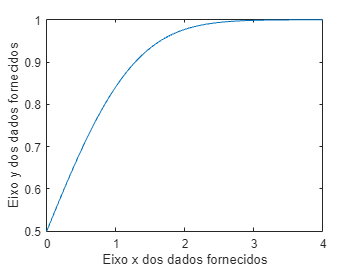

plot(xp,yp)
xlabel('Eixo x dos dados fornecidos');
ylabel('Eixo y dos dados fornecidos');

Número de graus de Liberdade da Função:

n=4;

Estrutura da função:

%função potência: y=a+bx+cx^2+dx^3

Criação da matriz de regressão linear:

A=regre_matrix(xp,n);

Criação do vetor de termos independentes:

b= independent_vector(xp,yp,n);

Solução da equação com os coeficientes:

%cálculo dos coeficientes:
S=linsolve(A,b);
coef=flipud(S);

Função interpolada com os pontos:

f=poly2sym(coef);

Plotagem dos pontos com a função interpolada:

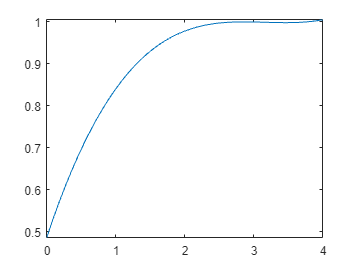

fplot(f,[xp(1) xp(end)])

Matriz de regressão linear

function A=regre_matrix(x,n)
A=zeros(n,n);
for i=1:n
    for j=1:n
        A(i,j)=sum(x.^(abs(j+i)-2)); 
    end
end
end

Vetor de termos independentes

function b= independent_vector(x,y,n)
b=zeros(n,1);
for i=1:n
b(i,1)=sum(x.^(i-1).*y);
end
end